# PRE LAB#4

Ashkan Jafari

810197483

Note that all of the functions are at the end of the report...

## Q1)

bit_gen(5,4)

ans =      0     0     1     1
     1     0     0     1
     1     1     1     0
     0     1     1     1
     1     1     1     0


## Q2)

[cons4, Es_avg] = constellation(4, 'pam')

cons4 =    -1.3416
   -0.4472
    0.4472
    1.3416


Es_avg = 1

[cons8, Es_avg] = constellation(8, 'pam')

cons8 =    -1.5275
   -1.0911
   -0.6547
   -0.2182
    0.2182
    0.6547
    1.0911
    1.5275


Es_avg = 1.0000

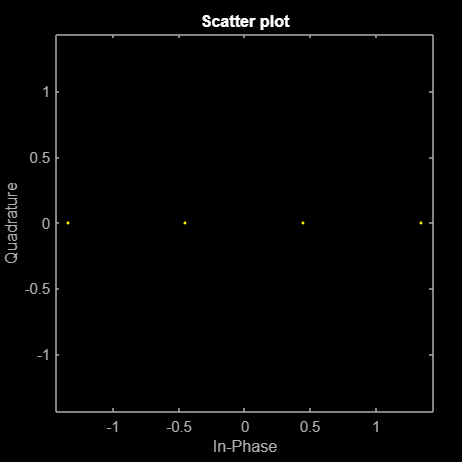

scatterplot(cons4)

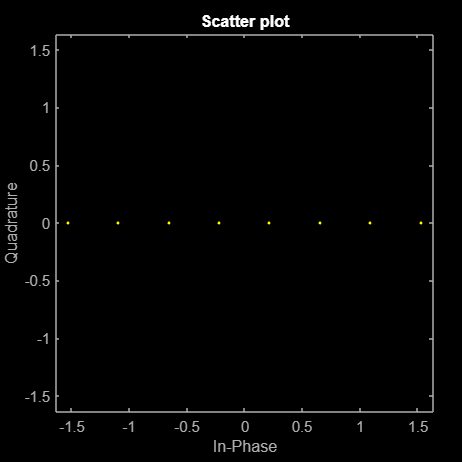

scatterplot(cons8)

## Q3)

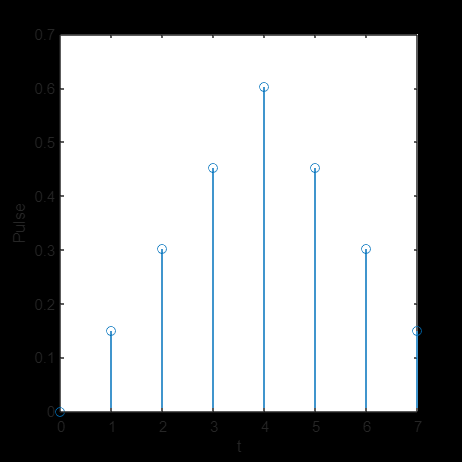

fs = 1;
smpl_per_symbl = 8;
n_fft = 256;
[p, t] = pulse_shape('triangular', fs, smpl_per_symbl);
stem(t,p)
title('Pulse Shape')
xlabel('t')
ylabel('Pulse')

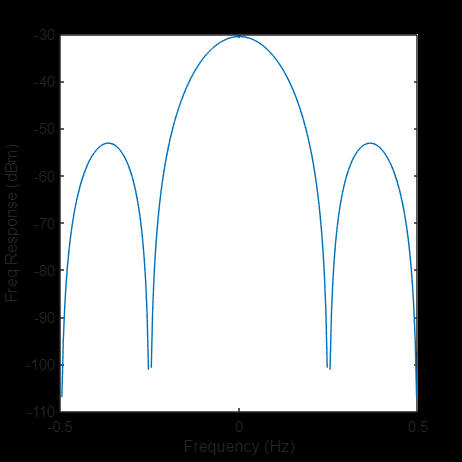

[s, freq] = Freq_res_db(p, fs, n_fft);
plot(freq, s)
title('Frequency response in dB of Rectangular Pulse Shape')
xlabel('Frequency (Hz)')
ylabel('Freq Response (dBm)')

## Functions.

function [b] = bit_gen(N,k)
b = randi([0 1],N,k);
end

function [cons, Es_avg] = constellation(M, modulation)
switch modulation
    case 'pam'
        m = transpose(1:M);
        cons = 2 * m - 1 - M;
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
end
end

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end
end

function [s, freq] = Freq_res_db(x, fs, n_fft)
freq = transpose((0:n_fft-1)/n_fft * fs - fs/2);
Xf = fftshift(fft(x, n_fft))/n_fft;
R = 50;
s =  10 * log10(abs(Xf).^2/(2*R)) + 30;
end